**Data**

x = [0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000];

y = [0.1409    0.1651    0.1506    0.2174    0.2374    0.2517    0.3091    0.3803    0.4700    0.5536    0.6137];


**Plot data**

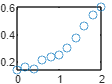

plot(x,y,'o');

**Transform data**

x;
new_y = log(y) ;

**Perform linear regression & plot dataset + fitted line**

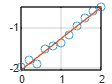

[a,r2] = linregr (x,new_y);

**Computer parameters of nonlinear equation from the fitted line**

alpha = exp(a(2)) % e^a0

alpha = 0.1297

beta = a(1) % a1

beta = 0.7724

**Plot the original data with the best fit nonlinear curve**

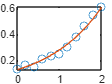

xx = 0 : 0.1 : 2;
yy = alpha * exp(beta * xx);
plot(x, y, 'o', xx, yy, '-')

**Predict the value of y for the given x**

xtest = 1.1;
predict_y = alpha * exp(beta * xtest)

predict_y = 0.3033